**MODERN CONTROL**

Flight control design: Yaw Turn tracking at defined radius.

State-space model: Lateral linearized model.

clear
R = 2000; %m
Ue = 67; %m
[angle_deg,rate] = Rtool(R,Ue)

angle_deg = 12.8873

rate = 0.0335

Design requirements: The correct tracking of a command r1 = 180 degrees($\psi =180\;\deg$), r2 v = 0 [m/s], r3 = 0.1617 rad ($\phi =0\ldotp 1617\;\textrm{rad}|9\ldotp 2633\;\deg$);

r2 will minimize sideslip angle and lateral velocity for passenger confort.

Modern Control Method: LQT

clear
load LatrMatsYaw.mat
A_latr

A_latr =    -0.1855   -0.1947  -66.4444    9.8100         0
   -0.4540  -13.0948    2.1590         0         0
    0.1392   -0.3625   -1.2217         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0


A1_latr = A_latr;
B_latr

B_latr =          0    5.9138
  -75.4745    4.8449
   -3.4309  -10.2450
         0         0
         0         0


B1_latr = B_latr;
C1_latr = eye(5);
D1_latr = zeros(5,2);

The state is $x={\left\lbrack v,p,r,\phi ,\psi \right\rbrack }^T$. We included the equation for yaw rate:


$$\dot{\psi} =\frac{r}{\cos \left(\theta_e \right)}$$


This equation include steady flight and small perturbations conditions.

We will need aileron control for heading hold, then the actuator dynamics from Stevens book will be:


$$\delta_a =\frac{1}{T_a s+1}u_a ,T_a =0\ldotp 0495$$


Include in matrix:

A_latr(1:5,6) = B_latr(:,1)

A_latr =    -0.1855   -0.1947  -66.4444    9.8100         0         0
   -0.4540  -13.0948    2.1590         0         0  -75.4745
    0.1392   -0.3625   -1.2217         0         0   -3.4309
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0


T_a = 0.0495;
A_latr(6,1:6) = [0,0,0,0,0,-1/T_a]

A_latr =    -0.1855   -0.1947  -66.4444    9.8100         0         0
   -0.4540  -13.0948    2.1590         0         0  -75.4745
    0.1392   -0.3625   -1.2217         0         0   -3.4309
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0         0         0  -20.2020


Actuator dynamics for $\delta_r$:


$$\delta_r =\frac{1}{T_r s+1}u_r$$


% Actuator Dynamics TF
T_r = 0.0495; % Value from Stevens Book page 442
A_latr(1:6,7) = [B_latr(:,2);0]

A_latr =    -0.1855   -0.1947  -66.4444    9.8100         0         0    5.9138
   -0.4540  -13.0948    2.1590         0         0  -75.4745    4.8449
    0.1392   -0.3625   -1.2217         0         0   -3.4309  -10.2450
         0    1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0         0
         0         0         0         0         0  -20.2020         0


A_latr(7,1:7) = [0,0,0,0,0,0,-1/T_r]

A_latr =    -0.1855   -0.1947  -66.4444    9.8100         0         0    5.9138
   -0.4540  -13.0948    2.1590         0         0  -75.4745    4.8449
    0.1392   -0.3625   -1.2217         0         0   -3.4309  -10.2450
         0    1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0         0
         0         0         0         0         0  -20.2020         0
         0         0         0         0         0         0  -20.2020


B_latr = [0,0;0,0;0,0;0,0;0,0;1/T_a,0;0,1/T_r]

B_latr =          0         0
         0         0
         0         0
         0         0
         0         0
   20.2020         0
         0   20.2020


Next, we need commands for tracking yaw angle, lateral speed, and roll angle and their state following:


$$\dot{\epsilon} =\left\lbrack \begin{array}{c}
\dot{\epsilon_1 } \\
\dot{\epsilon_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
r_1 -r\\
r_2 -\phi 
\end{array}\right\rbrack$$


A_latr(1:7,8) = zeros(7,1)

A_latr =    -0.1855   -0.1947  -66.4444    9.8100         0         0    5.9138         0
   -0.4540  -13.0948    2.1590         0         0  -75.4745    4.8449         0
    0.1392   -0.3625   -1.2217         0         0   -3.4309  -10.2450         0
         0    1.0000         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0
         0         0         0         0         0  -20.2020         0         0
         0         0         0         0         0         0  -20.2020         0


A_latr(8,1:8) = [0,0,-1,0,0,0,0,0]

A_latr =    -0.1855   -0.1947  -66.4444    9.8100         0         0    5.9138         0
   -0.4540  -13.0948    2.1590         0         0  -75.4745    4.8449         0
    0.1392   -0.3625   -1.2217         0         0   -3.4309  -10.2450         0
         0    1.0000         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0
         0         0         0         0         0  -20.2020         0         0
         0         0         0         0         0         0  -20.2020         0
         0         0   -1.0000         0         0         0         0         0


A_latr(1:8,9) = zeros(8,1)

A_latr =    -0.1855   -0.1947  -66.4444    9.8100         0         0    5.9138         0         0
   -0.4540  -13.0948    2.1590         0         0  -75.4745    4.8449         0         0
    0.1392   -0.3625   -1.2217         0         0   -3.4309  -10.2450         0         0
         0    1.0000         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0  -20.2020         0         0         0
         0         0         0         0         0         0  -20.2020         0         0
         0         0   -1.0000         0         0         0         0         0         0


A_latr(9,1:9) = [0,0,0,-1,0,0,0,0,0]

A_latr =    -0.1855   -0.1947  -66.4444    9.8100         0         0    5.9138         0         0
   -0.4540  -13.0948    2.1590         0         0  -75.4745    4.8449         0         0
    0.1392   -0.3625   -1.2217         0         0   -3.4309  -10.2450         0         0
         0    1.0000         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0  -20.2020         0         0         0
         0         0         0         0         0         0  -20.2020         0         0
         0         0   -1.0000         0         0         0         0         0         0
         0         0         0   -1.0000         0         0         0         0         0


B_latr = [B_latr;zeros(2)]

B_latr =          0         0
         0         0
         0         0
         0         0
         0         0
   20.2020         0
         0   20.2020
         0         0
         0         0


So far, the state is ${x=\left\lbrack v,p,r,\phi ,\psi ,\delta_a ,\delta_r ,\epsilon_1 ,\epsilon_2 \right\rbrack }^T$ and the input $u={\left\lbrack u_a ,u_r \right\rbrack }^T$

Now, E matrix for commands ${\left\lbrack r_1 ,r_2 \right\rbrack }^T$:

E = [zeros(7,2);[1,0];[0,1]]

E =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     1     0
     0     1


H matrix for LQR design:

H = [0,0,1,0,0,0,0,0,0;0,0,0,1,0,0,0,0,0]

H =      0     0     1     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0


Now, LQR gains for state feedback:

Q = H' * H;
Q(5,5) = 1;
Q(8,8) = 90000;
Q(9,9) = 1000;
Q = 1000*Q;
R = eye(2);
R(1,1) = 300*R(1,1);
R(2,2) = 1*R(1,1);
[K,P] = lqr(A_latr,B_latr,Q,R);
K1 = K;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Matrices for SIMULINK
K_eps_latr = K(:,8:9);
K_deltas_latr = K(:,6:7);
K_lqr_latr = K(:,1:5);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Closed loop observation:

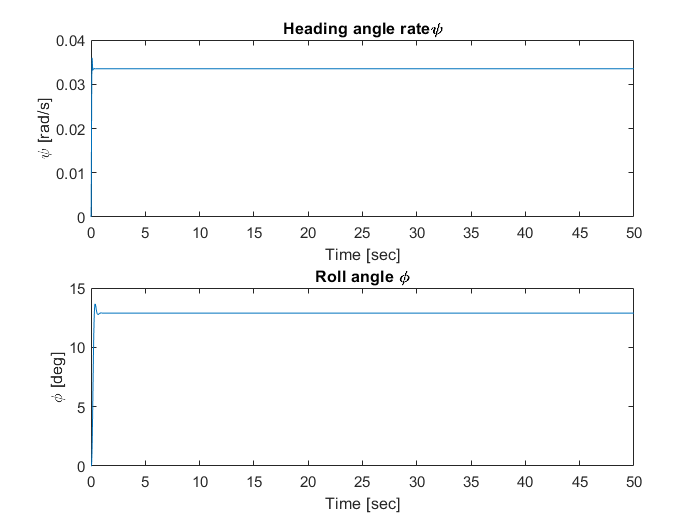

Ac = A_latr-B_latr*K;
Bc = E;
sys_cl = ss(Ac,Bc,H,0);
t = 0:0.01:50;
opt = stepDataOptions;
opt.StepAmplitude = [0.0335;deg2rad(12.88)]; 
[y1,t1,x1] = step(sys_cl,t,opt);
figure
subplot(2,1,1)
y_yaw1 = y1(:,1,1);
plot(t1,y_yaw1)
title('Heading angle rate\psi')
xlabel('Time [sec]')
ylabel('\psi [rad/s]')
subplot(2,1,2)
y_roll1 = rad2deg(y1(:,2,2));
plot(t1,y_roll1)
title('Roll angle \phi')
xlabel('Time [sec]')
ylabel('\phi [deg]')

Include observer:

Q = 1;
R = 1/20 * eye(9); %Measurement Noise
R(8,8) = 1;
R(9,9) = 1;
C_latr = eye(9);
[K,P] =lqr(A_latr',C_latr',Q,R);
L = K';

Closed loop system with observer:

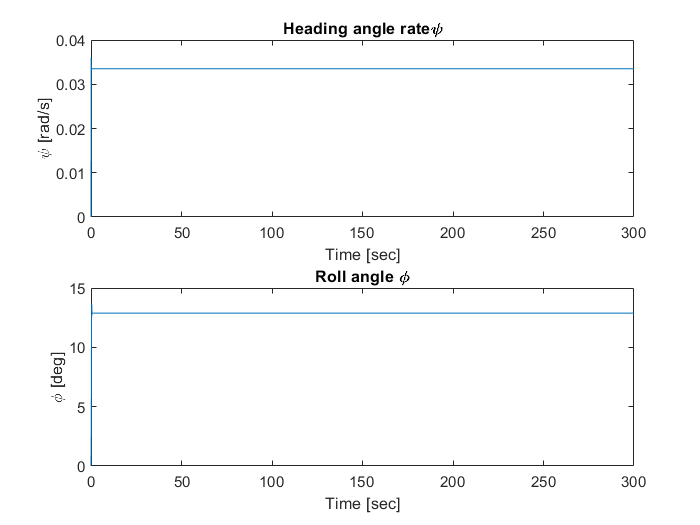

A_cl = [A_latr - B_latr*K1, B_latr*K1;zeros(9),A_latr - L];
B_cl = [E;zeros(9,2)];
H_cl = [H,zeros(2,9)];
C_cl = [C_latr,zeros(9,9)];
sys_cl = ss(A_cl,B_cl,H_cl,0);
t = 0:0.01:300;
opt = stepDataOptions;
opt.StepAmplitude = [0.0335;deg2rad(12.88)]; % Input command of r1 = 90 [deg] and r2=0 [m/s]
[y1,t1,x1] = step(sys_cl,t,opt);

figure
subplot(2,1,1)
y_yaw1 = y1(:,1,1);
plot(t1,y_yaw1)
title('Heading angle rate\psi')
xlabel('Time [sec]')
ylabel('\psi [rad/s]')
subplot(2,1,2)
y_roll1 = rad2deg(y1(:,2,2));
plot(t1,y_roll1)
title('Roll angle \phi')
xlabel('Time [sec]')
ylabel('\phi [deg]')

COMPARE ACTUAL STATE AND ESTIMATED STATE THROUGH ERROR STATE:

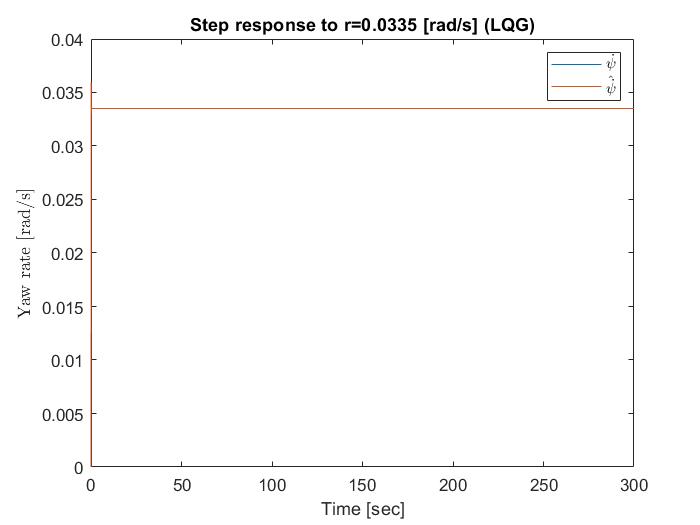

st1 = y_yaw1;
st1_err = x1(:,12,1);
est_st1 = st1 - st1_err;
figure
plot(t1,st1,t1,est_st1)
legend({'$\dot{\psi}$','$\hat{\dot{\psi}}$'},'Interpreter','latex')
xlabel('Time [sec]')
ylabel('Yaw rate [rad/s]','Interpreter','latex')
title('Step response to r=0.0335 [rad/s] (LQG)')

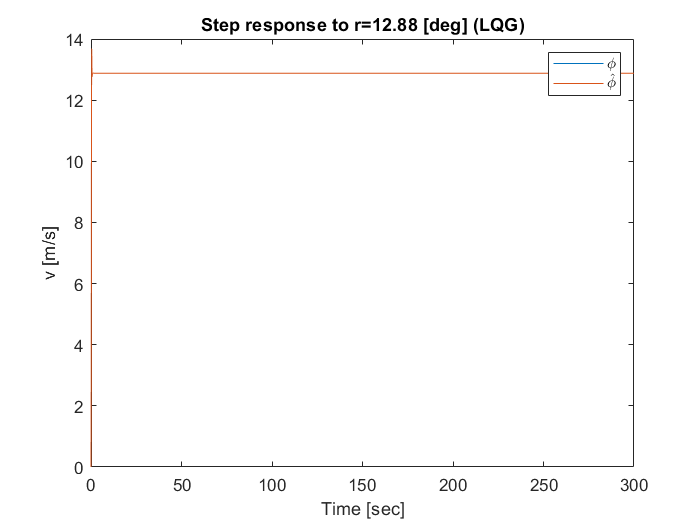

st1 = y_roll1;
st1_err = x1(:,13,1);
est_st1 = st1 - st1_err;
figure
plot(t1,st1,t1,est_st1)
legend({'$\phi$','$\hat{\phi}$'},'Interpreter','latex')
xlabel('Time [sec]')
ylabel('v [m/s]')
title('Step response to r=12.88 [deg] (LQG)')